# Naive model construction, FBA analysis and visualisation

## I. Creating the models for cells in RPMI medium

load('recon22.mat');
model = recon22;
RPMImediumSimulation;


% Import the gene expression data
gxData = readtable('DATASET SenescenceGEM_ControlSen_geneExpressionData.txt');

%With the lines of coding below, we "separate" the control and senescence data
controlData= gxData(:,[1,2,3,4]);
senescenceData= gxData(:,[1,2,3,5]);

% Create an index of all genes with expression of 0
indexControl = string(table2array(controlData(:,4))) == '0';
indexSenescence = string(table2array(senescenceData(:,4))) == '0';

% Remove genes with 0 expression from model
genesToRemoveControl = intersect(table2cell(controlData(indexControl,2)), modelRPMI.genes);
[modelRPMIcontrol, hasEffectControl, constrRxnNamesControl, deletedGenesControl] =... 
    deleteModelGenes(modelRPMI, genesToRemoveControl);

genesToRemoveSenescence = intersect(table2cell(senescenceData(indexSenescence,2)), modelRPMI.genes);
[modelRPMIsenescence, hasEffectSenescence, constrRxnNamesSenescence, deletedGenesSenescence] =... 
    deleteModelGenes(modelRPMI, genesToRemoveSenescence);

## II. (Defining the conditions for) FBA analysis

changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2019b.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. No solver set for this problemtype 



% Naming our models
modelControl=modelRPMIcontrol;
modelSenescence=modelRPMIsenescence;


% Choosing an objective function

% modelControl = changeObjective(modelControl, 'DM_atp_c_');
% modelSenescence = changeObjective(modelSenescence, 'DM_atp_c_');
 
% modelControl=addReaction(modelControl, 'NADHox',...
% 'reactionFormula', 'o2[c] + 2 nadh[c] + 2 h[c] -> 2 nad[c] + 2 h2o[c]');
%     modelControl= changeObjective(modelControl, 'NADHox');
%     modelControl.subSystems(7786)= modelControl.subSystems(4)
% modelSenescence=addReaction(modelSenescence, 'NADHox',...
% 'reactionFormula', 'o2[c] + 2 nadh[c] + 2 h[c] -> 2 nad[c] + 2 h2o[c]');
%     modelSenescence= changeObjective(modelSenescence, 'NADHox');
% modelSenescence.subSystems(7786)= modelSenescence.subSystems(4);

% modelControl = addReaction(modelControl, 'NADPHox',...
% 'reactionFormula', 'o2[c] + 2 nadph[c] + 2 h[c] -> 2 nadp[c] + 2 h2o[c]');

NADPHox	2 h[c] + 2 nadph[c] + o2[c] 	->	2 h2o[c] + 2 nadp[c] 


%     modelControl= changeObjective(modelControl, 'NADPHox');
% modelControl.subSystems(7786)= modelControl.subSystems(4)

modelControl = struct with fields:
        modelVersion: [1×1 struct]
                rxns: {7786×1 cell}
                mets: {5324×1 cell}
                   S: [5324×7786 double]
                 rev: [7786×1 double]
                   c: [7786×1 double]
            metNames: {5324×1 cell}
         metFormulas: {5324×1 cell}
                  lb: [7786×1 double]
                  ub: [7786×1 double]
           metCharge: [5324×1 double]
               rules: {7786×1 cell}
               genes: {1675×1 cell}
          rxnGeneMat: [7786×1675 double]
             grRules: {7786×1 cell}
          subSystems: {7786×1 cell}
    confidenceScores: {7786×1 cell}
       rxnReferences: {7786×1 cell}
        rxnECNumbers: {7786×1 cell}
            rxnNotes: {7786×1 cell}
            rxnNames: {7786×1 cell}
          metChEBIID: {5324×1 cell}
             metHMDB: {5324×1 cell}
           metKEGGID: {5324×1 cell}
        metPubChemID: {5324×1 cell}
      metInChIString: {5324×1 cell}
          

% modelSenescence=addReaction(modelSenescence, 'NADPHox',...
% 'reactionFormula', 'o2[c] + 2 nadph[c] + 2 h[c] -> 2 nadp[c] + 2 h2o[c]');

NADPHox	2 h[c] + 2 nadph[c] + o2[c] 	->	2 h2o[c] + 2 nadp[c] 


%     modelSenescence= changeObjective(modelSenescence, 'NADPHox');
% modelSenescence.subSystems(7786)= modelSenescence.subSystems(4);

objective = checkObjective(modelControl);

summaryT = 5×5 table
    Coefficient    Metabolite    metID    Reaction    RxnID
    ___________    __________    _____    ________    _____

         2          h2o[c]       3332     NADPHox     7786 
        -2          h[c]         3342     NADPHox     7786 
         2          nadp[c]      3953     NADPHox     7786 
        -2          nadph[c]     3960     NADPHox     7786 
        -1          o2[c]        4010     NADPHox     7786 


% Setting reactions bounds (optional)

% FBA optimalization
modelControl = changeRxnBounds(modelControl, 'EX_o2(e)', -1000, 'l');
modelSenescence = changeRxnBounds(modelSenescence, 'EX_o2(e)', -1000, 'l');

% Performing FBA analysis
FBAControl = optimizeCbModel(modelControl, 'max');
FBASenescence = optimizeCbModel(modelSenescence, 'max');

## III. Visualisation of results

% % Search and display all reactions with a certain metabolite
% surfNet(modelControl, 'atp[c]', 0,FBAControl.x,1,1)
% surfNet(modelSenescence, 'atp[c]', 0,FBASenescence.x,1,1)

% % Create a graph showing flux differences between the control and senescence model (requires bionformatics toolbox)
% buildFluxDistLayoutDiff(model, FBAControl, FBASenescence,'Normal versus Senescence');
% 
% draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAControl.v);
% draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBASenescence.v);
% 
% map=readCbMap('testMap.txt');
% options.zeroFluxWidth = 0.1;
% options.rxnDirMultiplier = 10;
% drawCbMap(map);

Create a table showing the flux values of the control and senescent model side-by-side for all reactions within the chosen subSystem

energySubSystems = {'Pyruvate metabolism'}; % Change this purple bit to whichever subsystem you want to investigate
% choose: 'Pyruvate metabolism','Citric acid cycle', 'Glycolysis/gluconeogenesis'
model = modelControl; 
energyReactions = model.rxns(ismember(model.subSystems,energySubSystems));
[~,energy_rxnID] = ismember(energyReactions,model.rxns);
reactionFluxesControl = FBAControl.v(energy_rxnID);
reactionNames = model.rxnNames(energy_rxnID);
reactionFormulas = printRxnFormula(model,energyReactions,0);
T1 = table(reactionNames,reactionFormulas,'RowNames',energyReactions);
T2= table(reactionFluxesControl);
controlFluxTable = [T1,T2];

model = modelSenescence; 
energyReactions = model.rxns(ismember(model.subSystems,energySubSystems));
[~,energy_rxnID] = ismember(energyReactions,model.rxns);
reactionFluxesSenescence = FBASenescence.v(energy_rxnID);
reactionNames = model.rxnNames(energy_rxnID);
reactionFormulas = printRxnFormula(model,energyReactions,0);
T1 = table(reactionNames,reactionFormulas,'RowNames',energyReactions);
T2= table(reactionFluxesSenescence);
SenescenceFluxTable = [T1,T2];

FluxTable=[controlFluxTable,SenescenceFluxTable(:,{'reactionFluxesSenescence'})]

FluxTable = 30×4 table
                                         reactionNames                                                           reactionFormulas                                  reactionFluxesControl    reactionFluxesSenescence
                ________________________________________________________________    ___________________________________________________________________________    _____________________    ________________________

    ACOAHi      {'acetyl-CoA hydrolase'                                        }    {'accoa[c] + h2o[c]  -> ac[c] + coa[c] + h[c] '                           }                0                         0          
    ACTLMO      {'acetol monooxygenase'                                        }    {'acetol[c] + h[c] + nadph[c] + o2[c]  -> 2 h2o[c] + mthgxl[c] + nadp[c] '}        

## IV. FVA

Perform Flux Variability Analysis on the reactions involved in the subSystem as defined in section III, and construct a table showing the FVA results (next to the previously constructed FluxTable).

model = modelControl;
energyReactions = model.rxns(ismember(model.subSystems,energySubSystems));
rxnsList = energyReactions;
[minFluxControl, maxFluxControl] = fluxVariability(model, 100, 'max', rxnsList);
fluxRangeControl= minus(maxFluxControl,minFluxControl);

model = modelSenescence;
energyReactions = model.rxns(ismember(model.subSystems,energySubSystems));
rxnsList = energyReactions;
[minFluxSenescence, maxFluxSenescence] = fluxVariability(model, 100, 'max', rxnsList);
fluxRangeSenescence= minus(maxFluxSenescence,minFluxSenescence);

fluxRangeDifference= minus(fluxRangeSenescence,fluxRangeControl);

% Creating a table that shows the FVA results
minFluxControl= table(minFluxControl);
maxFluxControl= table(maxFluxControl);
fluxRangeControl=table(fluxRangeControl);

minFluxSenescence= table(minFluxSenescence);
maxFluxSenescence= table(maxFluxSenescence);
fluxRangeSenescence=table(fluxRangeSenescence);

fluxRangeDifference= table(fluxRangeDifference);

FluxVariabilityTable=[FluxTable,minFluxControl,maxFluxControl,fluxRangeControl,minFluxSenescence,maxFluxSenescence,fluxRangeSenescence,fluxRangeDifference]

FluxVariabilityTable = 30×11 table
                                         reactionNames                                                           reactionFormulas                                  reactionFluxesControl    reactionFluxesSenescence    minFluxControl    maxFluxControl    fluxRangeControl    minFluxSenescence    maxFluxSenescence    fluxRangeSenescence    fluxRangeDifference
                ________________________________________________________________    ___________________________________________________________________________    _____________________    ________________________    ______________    ______________    ________________    _________________

## fisualize variability graph

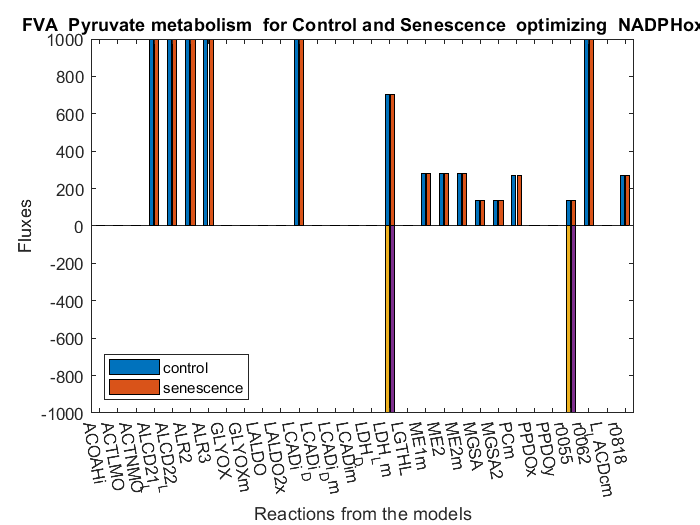

minf = [minFluxControl, minFluxSenescence];
maxf = [maxFluxControl, maxFluxSenescence];
maxfxs =table2cell(maxf) ;
minfxs = table2cell(minf);

s=size(minf,1);
step=1;
x(:,1)=[step:step:s*step];

figure
plot1 = bar(cell2mat(maxfxs(1:end, :)));
hold on
plot2 = bar(cell2mat(minfxs(1:end, :)));
hold off
xticks(x)
xticklabels(energyReactions)
set(gca, 'XTickLabelRotation', -80);
yticks([-1000 -800 -600 -400 -200 0 200 400 600 800 1000])
xlabel('Reactions from the models')
ylabel('Fluxes')
legend({'control', 'senescence'}, 'Location', 'southwest')
title1=['FVA ',energySubSystems(1,1), ' for Control and Senescence', ' optimizing ', objective ]; 

title3=join(title1);


title(title3)

x=[];

## Optional steps that might enhance analysis (yet to be completed)

% % Add a reaction of interest to the model (suggested by Marian)
% 
% model = addReaction(model, 'NADHox',...
% 'reactionFormula', 'o2[c] + 2 nadh[c] + 2 h[c] -> 2 nad[c] + 2 h2o[c]');
% 
% % [messageOut] = buildReactionIDlayout(FBAControl., 'Normal versus Senescence')